# Gabriel Colangelo

clear
close all
clc

## Problem 4a) Actual TOF

% Timeline dates
launch_date         = juliandate(datetime(2004,08,03));
venus_flyby_date    = juliandate(datetime(2006,10,24));
mercury_flyby_date  = juliandate(datetime(2008,1,14));
moi_date            = juliandate(datetime(2011,3,18));

% Calculate TOF
TOF_venus_flyby     = venus_flyby_date - launch_date;
TOF_mercury_flyby   = mercury_flyby_date - launch_date;
TOF_moi             = moi_date - launch_date;

fprintf(['TOF for venus flyby is %.1f JD \n',...
         'TOF for mercury flyby is %.1f JD \n',...
         'TOF for MOI is %.1f JD'],TOF_venus_flyby, TOF_mercury_flyby, TOF_moi)

TOF for venus flyby is 812.0 JD 
TOF for mercury flyby is 1259.0 JD 
TOF for MOI is 2418.0 JD

**The TOF for Earth launch to the first Venus flyby is 812 Julian days. The TOF for Earth launch to first Mercury flyby is 1259 Julian Days. The TOF for Earth launch to MOI (Mercury Orbit Insertion) is 2418 Julian days.**

## Problem 4b) Hohmann transfer from Earth-to-Mercury

Find**:** TOF from Earth to Venus

Assume: All planetary orbits are co-planar and circular and use patched conics

% Planet circular radius about sun
r_sun_mercury       = 57909101;
r_sun_earth         = 149597898;
r_sun_venus         = 108207284;

% Planetary and Sun properties
mu_sun              = 132712440017.99;
R_venus             = 6051.9;
mu_venus            = 324858.59882646;

% Semi-major axis of hohmann arc
a_hohmann           = (r_sun_earth + r_sun_mercury)/2;

% Eccentricity of hohmann arc 
e_hohmann           = 1 - r_sun_mercury/a_hohmann;

% Semi-latus rectum of hohmann arc
p_hohmann           = a_hohmann*(1 - e_hohmann^2);

% True anomaly at venus encounter - moving from apoapsis to periapsis so descending
theta_venus         = -acosd(((p_hohmann/r_sun_venus) - 1)/e_hohmann);

% Eccentric anomaly at venus
E_venus             = wrapTo2Pi(2*atan(tand(theta_venus/2)/sqrt((1+e_hohmann)/(1-e_hohmann))));

% Eccentric anomaly at Earth (apoapsis, so theta = 180)
E_earth             =2*atan(tand(180/2)/sqrt((1+e_hohmann)/(1-e_hohmann)));

% Mean Anomaly at venus
M_venus             = E_venus - e_hohmann*sin(E_venus);

% Mean Anomaly at Earth
M_earth             = E_earth - e_hohmann*sin(E_earth);

% Mean motion
n_hohmann           = sqrt(mu_sun/a_hohmann^3);

% Time of flight from Earth to venus
TOF_venus           = (M_venus - M_earth)/n_hohmann;
fprintf('The time of flight from Earth to Venus is %.2f days',TOF_venus/(24*3600))

The time of flight from Earth to Venus is 64.24 days


$$r_{sun,mercury} = r_p \\
r_{sun,earth} = r_a \\
a = (r_a + r_p)/2 \\
e = 1 - \frac{r_p}{a} \\
p = a(1 - e^2) \\
r_{sun,venus} = \frac{p}{1 + e \cos{\theta^*}}  \ \text{ - Moving from apoapsis to periapsis, so $\theta^*$ < 0}\\
\tan({\frac{\theta^*}{2}) = \sqrt{\frac{1+e}{1-e}} \tan({\frac{E}{2}) \ \text{ - $\theta^*$ at Earth is 180 deg, as it is the apoapsis of the hohmann arc} \\

E = 2\tan^{-1}{[\tan({\frac{\theta^*}{2}) /\sqrt{\frac{1+e}{1-e}} ]} \\
M = E - e\sin{E} \\
M_{venus} = M_{earth} + \sqrt{\frac{\mu}{a^3}} \Delta t \\
T.O.F =\Delta t = \frac{M_{venus} - M_{earth}}{ \sqrt{\frac{\mu}{a^3}}}\\
\\
T.O.F. = 1541.8\ [hours] = 64.24\ [days] \ \text{ - Earth to Venus}$$


% Actual venus encounter
fprintf('The actual Venus encounter was %.2f Venus Radii', (2990 + R_venus)/R_venus)

The actual Venus encounter was 1.49 Venus Radii


$$r_{venus} = (R_{venus} + h_{venus})/R_{venus \\
r_{venus} = 1.49 \ [R_{venus}]$$


## Problem 4c)


$$\underline{Find}: a,e,r,v,\gamma,\theta^*, r_p,r_a,period,\Delta \omega, \text{for the post-encounter heliocentric orbit}$$


**To most effectively reach Mercury, it is desirable to lose energy as Mercury has a lower orbital energy than Earth. This is due to its much smaller semi-major axis/being closer to the sun. To lose energy on the Venus flyby, it is better to arrive ahead of Venus. **

% Closest encounter with Venus
rp_venus            = 4*R_venus;

% Heliocentric velocity of Venus
v_venus_sun         = sqrt(mu_sun/r_sun_venus);

% Heliocentric velocity of s/c magnitude at venus pre-encounter
v_minus_mag         = sqrt(2*(-mu_sun/(2*a_hohmann) + mu_sun/r_sun_venus));

% Specific angular momentum of hohmann arc
h_hohmann           = sqrt(mu_sun*p_hohmann);

% Calculate flight path angle
gamma_minus         = sign(theta_venus)*acosd(h_hohmann/(r_sun_venus*v_minus_mag));

% Heliocentric velocity of s/c at venus pre-encounter
v_minus             = [v_minus_mag*sind(gamma_minus);v_minus_mag*cosd(gamma_minus)];

% Excess velocity vector of s/c relative to venus prior to encounter
v_inf_venus_minus   = v_minus - [0;v_venus_sun];

% Specific energy of hyperbolic orbit about venus
energy_H            = norm(v_inf_venus_minus)^2/2;

% Semi major axis of hyperbolic orbit about venus
a_abs_H             = mu_venus/(2*energy_H);

% Eccentricity of hyperbolic orbit about venus
e_H                 = rp_venus/a_abs_H + 1;

% Flyby angle
delta               = 2*asind(1/e_H);

% Complementary angle, neta
eta                 = asind(v_minus_mag*sind(gamma_minus)/norm(v_inf_venus_minus));

% Heliocentric velocity magnitude post flyby
v_plus_mag          = sqrt(v_venus_sun^2 + norm(v_inf_venus_minus)^2 - 2*norm(v_inf_venus_minus)*v_venus_sun*cosd(eta+delta));
fprintf('The heliocentric velocity magnitude of sc post venus encounter is %.4f km/s',v_plus_mag)

The heliocentric velocity magnitude of sc post venus encounter is 32.6511 km/s


$$v_{venus/sun} = \sqrt{\frac{\mu_{sun}}{r_{sun,venus}}} \\
\epsilon = \frac{-\mu_{sun}}{2a} \\
v^- = \sqrt{2(\epsilon + \frac{\mu_{sun}}{r_{sun,venus}})} \ \text{ - Helioocentric velocity magnitude of sc at venus arrival}\\
h = \sqrt{p\mu_{sun}} \\
\cos{\gamma^-} = \frac{h}{v^- r_{sun,venus}} \ \text{ - Negative, descending} \\
\bar{v}^- = v^-\sin{\gamma^-} \ \hat{r} + v^-\cos{\gamma^-} \ \hat{\theta} = -15.08 \ \hat{r} + 30.76 \ \hat{\theta} \ [km/s]\\
\bar{v}_\infty^- = \bar{v}^- -\bar{v}_{venus/sun}  = -15.08 \ \hat{r} - 4.25 \ \hat{\theta} \ [km/s] \ \text{ - Excess velocity of s/c relative to venus} \\
|\bar{v}_\infty^+| = |\bar{v}_\infty^-| \ \text{ - Flyby doesn't change magnitude, only direction}\\
\epsilon_H = \frac{v_\infty^{-2}}{2} \ \text{ - Energy of hyperbolic orbit about venus} \\
|a| = \frac{\mu_{venus}}{2\epsilon_H} \\
 = 
e_H = (\frac{r_p}{|a|} + 1) \\
\sin{\frac{\delta}{2}} = \frac{1}{e_H}\\
\frac{v_\infty^-}{\sin{\gamma^-}}=\frac{v^-}{\sin{\eta}} \ \text{ - Law of sines}\\
v^{+2} = v_\infty^{+2} + v_{venus/sun} - 2v_{venus/sun} v_\infty^+\cos{(\eta + \delta)} \ \text{ - Law of cosines} \\
\\
v^+  = 32.651 \ [km/s]$$


% New flyby angle
gamma_plus          = asind(norm(v_inf_venus_minus)*sind(eta+delta)/v_plus_mag);
fprintf('The flight path angle post venus encounter is %.3f deg',gamma_plus)

The flight path angle post venus encounter is -26.481 deg


$$\frac{v_\infty^+}{\sin{\gamma^+}}=\frac{v^+}{\sin{(\eta + \delta)}} \ \text{ - Law of sines}\\ 
\\
\gamma^+ = -26.48 \ [deg]
\\
r = r_{sun,venus} =  108207284 \ [km]$$


% Calculate true anomaly post flyby in Heliocentric orbit
theta_plus            = atan2d((r_sun_venus*v_plus_mag^2/mu_sun)*cosd(gamma_plus)*sind(gamma_plus),...
                    ((r_sun_venus*v_plus_mag^2/mu_sun)*cosd(gamma_plus)^2 - 1));
fprintf('The true anomaly post venus encounter is %.3f deg', theta_plus)

The true anomaly post venus encounter is -131.188 deg


$$\tan{\theta^*} = \frac{\frac{r^+v^{+2}}{\mu_{sun}}\cos{\gamma^+}\sin{\gamma^+}}{\frac{r^+v^{+2}}{\mu_{sun}}\cos^2{\gamma^+} - 1} \\
\theta^{*+} = -132.19 \ [deg] \ \text{Negative due to descending, $\gamma$ < 0}$$


% Calculate eccentricity of heliocentric orbit
e_new              = sqrt((r_sun_venus*v_plus_mag^2/mu_sun - 1)^2*cosd(gamma_plus)^2 + sind(gamma_plus)^2);
fprintf('The heliocentric orbit eccentricity post venus encounter is %.4f ', e_new);

The heliocentric orbit eccentricity post venus encounter is 0.4610 


$$e^2 = (\frac{r^+v^{+2}}{\mu_{sun}} -1)^2\cos^2{\gamma^+} + \sin^2{\gamma^+} \\
e = 0.461$$


% Energy post flyby
energy_new          = v_plus_mag^2/2 - mu_sun/r_sun_venus;

% Calculate semi major axis post flyby
a_new               = -mu_sun/(2*energy_new);
fprintf('The heliocentric orbit semi major axis post encounter is %.5E km',a_new);

The heliocentric orbit semi major axis post encounter is 9.56945E+07 km


$$\epsilon = \frac{v^{+2}}{2} - \frac{\mu_{sun}}{r} \\
a = \frac{-\mu_{sun}}{2\epsilon} \\
\\
a = 9.569 \times 10^7 \ [km]$$


% Periapsis distance
rp_new               = a_new*(1 - e_new);
fprintf('The periapsis distance post encounter is %.3E km', rp_new);

The periapsis distance post encounter is 5.158E+07 km


$$r_p = a(1-e) \\
r_p = 5.1579 \times 10^7 \ [km]$$


% Apoapsis distance
ra_new                = a_new*(1 + e_new);
fprintf('The apoapsis distance post encounter is %.3E km', ra_new);

The apoapsis distance post encounter is 1.398E+08 km


$$r_a = a(1+e) \\
r_a = 1.3981 \times 10^8 \ [km]$$


% Period
tau_new               = 2*pi*sqrt(a_new^3/mu_sun);
fprintf('The heliocentric orbit period post encounter is %.1f days',tau_new/(24*3600));

The heliocentric orbit period post encounter is 186.9 days


$$Period = 2\pi\sqrt{\frac{a^3}{\mu_{sun}}} \\
Period = 186.9 \ [days]$$


% Change in argument of periapsis 
deltaAOP                = theta_venus - theta_plus;
fprintf('The change in argument of periapsis is %.3f deg ', deltaAOP)

The change in argument of periapsis is 10.069 deg 


$$\Delta \omega = \theta^{*-} - \theta^{*+} \\
\Delta \omega =  10.07  \ [deg]$$


## Problem 4d)


$$\underline{Find}: \Delta \bar{v}_{eq} , | \Delta \bar{v}_{eq}|, \alpha$$


% Heliocentric velocity vector of sc post encounter
v_plus                  = [v_plus_mag*sind(gamma_plus);v_plus_mag*cosd(gamma_plus)];

% Equivalent deltaV vector
dv_eq                   = v_plus - v_minus;


$$\bar{v}^+ = v^+\sin{\gamma^+} \ \hat{r} + v^+\cos{\gamma^+} \ \hat{\theta} = -14.56 \ \hat{r} + 29.22\ \hat{\theta} \ [km/s]\\

\Delta \bar{v}_{eq} = \bar{v}^+ - \bar{v}^- \\

\Delta \bar{v}_{eq}  = 0.5216 \ \hat{r} - 1.538 \ \hat{\theta} \ [km]$$


% Equivalent deltaV magnitude
dv_eq_mag                = norm(dv_eq);
fprintf('The equivalent deltaV magnitude is %.3f km/s',dv_eq_mag)

The equivalent deltaV magnitude is 1.624 km/s


$$|\Delta \bar{v}_{eq} | = 1.624 \ [km/s]$$


% Calculate beta
beta                = asind(v_plus_mag*sind(abs(gamma_plus - gamma_minus))/dv_eq_mag);

% Calculate alpha - increase in FPA, positive alpha
alpha               = sign(gamma_plus - gamma_minus)*(180 - beta);
fprintf('The equivalent deltaV alpha is %.3f deg', alpha)

The equivalent deltaV alpha is -172.620 deg


$$\Delta \gamma = \gamma^+ - \gamma^- \\

\frac{|\Delta v_{eq}|}{\sin{\Delta \gamma}} = \frac{v^+}{\sin{\beta}} \\

\beta = \sin^{-1}{\frac{v^+ \sin{\Delta \gamma}}{|\Delta v_{eq}|} \\

\alpha = 180 - \beta \\

\alpha = -172.62\ [deg] \ \text{ - decrease in flight path angle, negative}$$


## Problem 4e) Plot Orbits

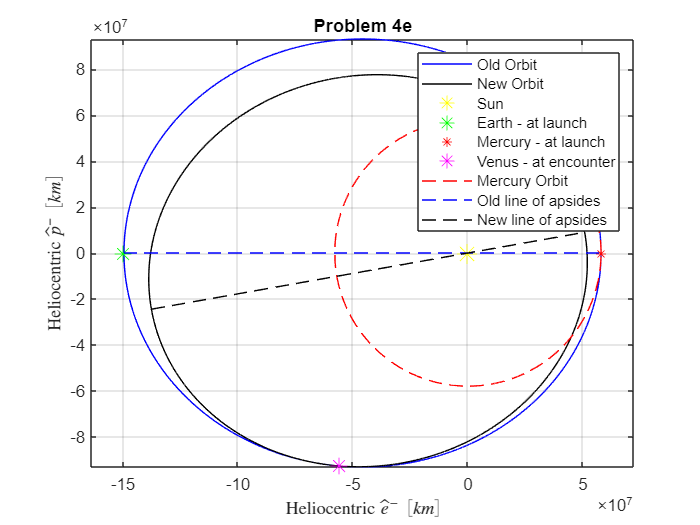

% Rotation matrix from new perifocal frame to original perifocal frame
Pminus_DCM_Pplus    = [cosd(deltaAOP), -sind(deltaAOP);...
                       sind(deltaAOP), cosd(deltaAOP)];

% True anomaly vector
ta_vec              = 0:.01:360;

% Initialize position vectors in perifocal frame
r_old_P             = zeros(2,length(ta_vec));
r_new_P             = r_old_P;
r_mercury_P         = r_old_P;
r_new               = zeros(1,length(ta_vec));

for i = 1:length(ta_vec)
        % DCM matrix from rotating orbit frame to perifocal frame
        P_DCM_R            = [cosd(ta_vec(i)), -sind(ta_vec(i));...
                              sind(ta_vec(i)), cosd(ta_vec(i))];

        % Calculate transfer orbit radii
        r_old              = (a_hohmann*(1 - e_hohmann^2))/(1 + e_hohmann*cosd(ta_vec(i)));

        % Calculate new transfer orbit radii
        r_new(i)           = (a_new*(1 - e_new^2))/(1 + e_new*cosd(ta_vec(i)));

        % Position vector in new perifocal frame
        r_new_Pplus        = P_DCM_R*[r_new(i);0];

        % Old Transfer orbit in perifocal frame
        r_old_P(:,i)       = P_DCM_R*[r_old;0];

        % New transfer orbit in old perifocal frame
        r_new_P(:,i)        = Pminus_DCM_Pplus*r_new_Pplus;

        % Merucry orbit
        r_mercury_P(:,i)    = P_DCM_R*[r_sun_mercury;0];

end

% Find venus encounter location
ind_venus = find(ta_vec >= (360 + theta_venus),1);

% Find periapsis and apoapsis
ind_ra    = find(r_new == max(abs(r_new)));
ind_rp    = find(r_new == min(abs(r_new)),1);

figure
plot(r_old_P(1,:),r_old_P(2,:),'-b')
hold on
plot(r_new_P(1,:),r_new_P(2,:),'-k')
plot(0, 0,'y*','MarkerSize',12)
plot(-r_sun_earth,0,'g*','MarkerSize',10)
plot(r_sun_mercury,0,'r*','MarkerSize',6)
plot(r_old_P(1,ind_venus),r_old_P(2,ind_venus),'m*','MarkerSize',10)
plot(r_mercury_P(1,:),r_mercury_P(2,:),'--r')
plot([-r_sun_earth r_sun_mercury],[0 0],'--b')
plot([r_new_P(1,ind_ra) r_new_P(1,1)],[r_new_P(2,ind_ra) r_new_P(2,1)],'--k')
xlabel('Heliocentric $\hat{e}^- \ [km]$', 'Interpreter','latex')
ylabel('Heliocentric $\hat{p}^- \ [km]$', 'Interpreter','latex')
grid on
axis equal
legend('Old Orbit','New Orbit','Sun','Earth - at launch','Mercury - at launch','Venus - at encounter','Mercury Orbit',...
       'Old line of apsides','New line of apsides')
title('Problem 4e')

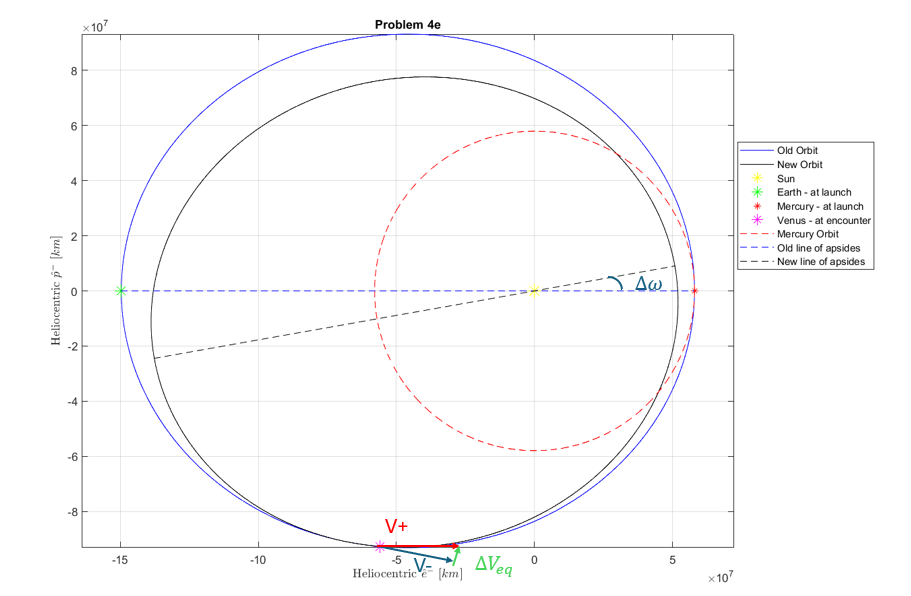

**The spacecraft (post venus encounter) crosses the orbit of Mercury at two different points, as observed in the figure above.**

% Eccentric anomaly at venus post encounter
E_venus_post        = wrapTo2Pi(2*atan(tand(theta_plus/2)/sqrt((1+e_new)/(1-e_new))));

% Semi-latus rectum post encounter
p_new               = a_new*(1 - e_new^2);

% True anomaly at mercury in new perifocal frame - descending
theta_mercury       = -acosd(((p_new/r_sun_mercury) - 1)/e_new);

% Eccentric anomaly at mercury 
E_mercury           = wrapTo2Pi(2*atan(tand(theta_mercury/2)/sqrt((1+e_new)/(1-e_new))));
 
% Mean Anomaly at venus post encounter
M_venus_post        = E_venus_post - e_new*sin(E_venus_post);

% Mean Anomaly at mercury
M_mercury           = E_mercury - e_new*sin(E_mercury);

% Mean motion
n_new               = sqrt(mu_sun/a_new^3);

% Time of flight from venus to mercury
TOF_mercury         = (M_mercury - M_venus_post)/n_new;
fprintf('The time of flight from Venus to mercury is %.2f days',TOF_mercury/(24*3600))

The time of flight from Venus to mercury is 33.07 days


$$p_{new} = a_{new}(1 - e_{new}^2) \\
r_{sun,mercury} = \frac{p_{new}}{1 + e_{new} \cos{\theta^*}}  \\
\\
 \text{Two crossings of Mercury orbit ($\theta^* = \pm 49.19$ deg), choose one closest to Venus encounter location. Descending, so $\theta^*$ < 0}\\
\\
\tan({\frac{\theta^*}{2}) = \sqrt{\frac{1+e}{1-e}} \tan({\frac{E}{2}) \ \text{ - Evaluate $\theta^*$ for both Venus and Mercury in new perifocal frame.} \\

E = 2\tan^{-1}{[\tan({\frac{\theta^*}{2}) /\sqrt{\frac{1+e_{new}}{1-e_{new}}} ]} \\
M = E - e_{new}\sin{E} \\
M_{mercury} = M_{venus} + \sqrt{\frac{\mu}{a_{new}^3}} \Delta t \\
T.O.F =\Delta t = \frac{M_{mercury} - M_{venus}}{ \sqrt{\frac{\mu}{a_{new}^3}}}\\
\\
T.O.F. = 793.7\ [hours] = 33.07\ [days] \ \text{ - Venus to Mercury}$$


**The calculated Earth to Venus leg T.O.F of 64 JD is extremely less than the actual T.O.F of 812 JD. Likewise, the calculated Venus to Mercury T.O.F of 33 days is much less than the actual T.O.F between the second Venus flyby (6/5/07) and the first Mercury flyby (1/14/08), which took 223 JD. The actual T.O.F. difference between the second venus flyby and the MOI is 1382 JD, an even more significant difference.  These differences are likely to due to the approximations made during the patched conics approach, such as assuming circular, co-planar orbits. The calculated T.O.F for both legs are extremely unreasonable.**

## Problem 4f)

% Mean motion for venus about sun
n_venus          = sqrt(mu_sun/r_sun_venus^3);

% Mean motion for mercury about sun
n_mercury        = sqrt(mu_sun/r_sun_mercury^3);

% Venus Transfer angle relative to Earth
TA_venus         = ((360 + theta_venus) - 180)*pi/180;

% Calculate phase angle of venus at depature
phase_venus      = (TA_venus - wrapTo2Pi(n_venus*TOF_venus))*180/pi;
fprintf('The phase angle between Earth and Venus is %.2f deg',phase_venus)

The phase angle between Earth and Venus is -44.04 deg


$$n_{venus} = \sqrt{\frac{\mu_{sun}}{r_{sun,venus}^3}} \\
T.A_{venus} = \theta^*_{encounter,Venus} - 
 \theta^*_{departure,Earth} \ \text{ - Earth at apoapsis,   $\theta^*_{departure,Earth} = \pi$}\\
(n_{venus})(T.O.F)_{venus} = T.A._{venus} - \phi \\
\\
\phi_{venus} = -44.04 \ [deg]$$


% Mercury Transfer angle relative to Earth
TA_mercury       = ((theta_mercury - theta_plus) + TA_venus)*pi/180;

% Calculate phase angle of venus at depature
phase_venus      = (TA_mercury - wrapTo2Pi(n_mercury*(TOF_venus + TOF_mercury)))*180/pi;
fprintf('The phase angle between Earth and Mercury is %.2f deg',phase_venus)

The phase angle between Earth and Mercury is 44.80 deg


$$n_{mercury} = \sqrt{\frac{\mu_{sun}}{r_{sun,mercury}^3}} \\
\text{ Transfer angle between Venus and Mercury, plus transfer angle between Venus and Earth, gives TA between Earth and Mercury} \\
T.A_{mercury} = (\theta^*_{arrival,mercury} - 
 \theta^*_{new,venus}) + T.A._{venus} \\
(n_{mercury})(T.O.F)_{venus+mercury} = T.A._{mercury} - \phi \\
\\
\phi_{mercury} = 44.8 \ [deg]$$
